mode = "adder_lbld";
file_path = sprintf('lbld/%s.txt',mode);
data = readmatrix(file_path);
data = sortrows(data,2);
cellIDs = data(:,2);
fixed = [0,0,0,0,0,0,0,0];
row = 1;
while(row<= 50000)
    if(data(row,2)==data(row+1,2) & data(row,3)==0 & data(row+1,3)==1)
        %if current and next row are for the same cell, and current length
        %is for birth, and next is for division, concatinate the current
        %and next row side by side and addd it to the fixed data and
        %increment by 2 rows prior to repeat
        new_row = [data(row,:) data(row+1,:)];
        fixed = [fixed;new_row];
        row = row +2;
    else
        row = row +1;
    end
end


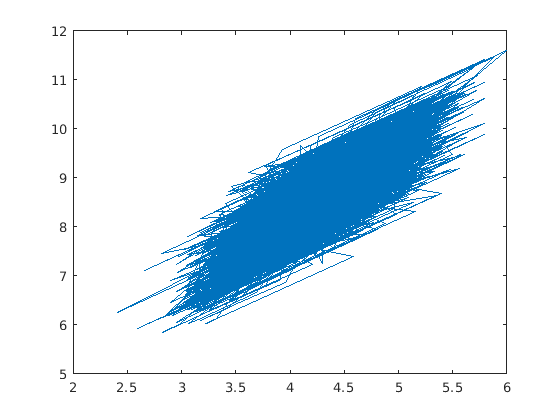

fixed(1,:)=[];  %remove first row of zeros

ld = fixed(:,8)+1;
lb = fixed(:,4)+1;
plot(lb,ld)

A = corrcoef(lb,ld)

A =     1.0000    0.8759
    0.8759    1.0000


det(A)

ans = 0.2328

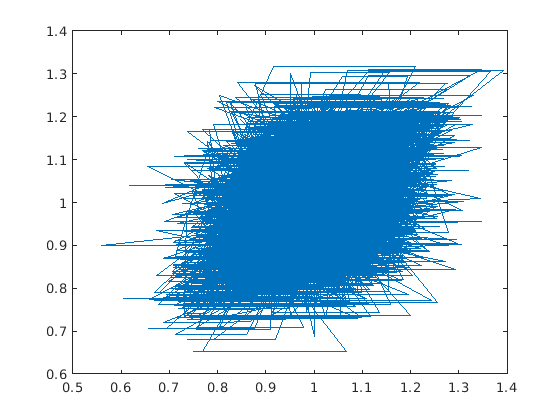

added_length = ld-lb;
rescaled_added_length = added_length/mean(added_length, "all");
rescaled_lb = lb/mean(lb, "all");
plot(rescaled_lb,rescaled_added_length);

B = corrcoef(rescaled_lb,rescaled_added_length)

B =     1.0000    0.5075
    0.5075    1.0000


det(B)

ans = 0.7425


fixed(:,9)=fixed(:,5)-fixed(:,1);
fixed(:,10)=fixed(:,8)-fixed(:,4);
